# Molico (2006) Replication

## Calibration

clear all
close all
clc

tic

mupper=7 %highest value if money holdings on the grid

mupper = 7

N=10000 %number of agents for simulating distribution

N = 10000

iterations=5 %maximum number of iterations for the value function iteration    

iterations = 5

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.25

x = 0.2500

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=1 %Money supply

M = 1

r=1/beta-1 %real interest rate

r = 0.0101

mu_all=[0,0.1] %Money Growth

mu_all =          0    0.1000


mu_labels={ 'Price Stability','10% inflation'}

mu_labels = 1×2 cell array
    {'Price Stability'}    {'10% inflation'}


n_calibration=size(mu_all)

n_calibration =      1     2


n_calibration=n_calibration(1,2)

n_calibration = 2

smoothing_parameter=0.3

smoothing_parameter = 0.3000

correct_dist=1

correct_dist = 1

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=8
% grids_2=8
% grids_3=3
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,0.80,grids_1)
% m_1=linspace(0.90,2, grids_2)
%  m_2=linspace(2.1,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=20

grids = 20

m=linspace(0,mupper ...
    , grids)

m =          0    0.3684    0.7368    1.1053    1.4737    1.8421    2.2105    2.5789    2.9474    3.3158    3.6842    4.0526    4.4211    4.7895    5.1579    5.5263    5.8947    6.2632    6.6316    7.0000


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function
test_utility=0; % displays the utility and cost function

display_plot_all=1;
display_plot_V=1;
display_plot_q=1;
display_plot_d=1;
display_plot_meeting=1;
display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=1;
display_plot_cdf=0;
display_plot_money_savings=0;
display_plot_M_Track_1=1;
display_plot_q_all=1;
display_plot_d_all=1;






## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids);
m_savings_2=zeros(1,grids);
m_savings_3=zeros(1,grids);

V_all=zeros(grids,n_calibration);
Distribution_all=zeros(N,n_calibration);
q_all=zeros(grids, grids,n_calibration);
d_all=zeros(grids, grids,n_calibration);
lamdba_all=zeros(grids,n_calibration);
price_all=zeros(grids, grids,n_calibration);
f=zeros(100,n_calibration);
xi=zeros(100,n_calibration);
M_track_1=zeros(iterations,n_calibration);

average_price=zeros(1,n_calibration);
std_distribution=zeros(1,n_calibration);
velocity=zeros(1,n_calibration);
average_real_balances=zeros(1,n_calibration);

## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M_0=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

 for calibriation=1:n_calibration
mu=mu_all(1,calibriation);
[V_all(:,calibriation), q_all(:,:,calibriation),d_all(:,:,calibriation),Distribution_all(:,calibriation),...
    lamdba,cdf,M_track_1(:,calibriation), M_track_2,Meeting,i] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,M_0,r,alpha,x,mu,theta,mupper, stopping_parameter,correct_dist);

 if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
 end



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053         0         0         0         0


Distribution_new =     0.9799    1.2306    1.1053    1.1053    1.1053    1.2306    0.9799    1.1053    1.2306    0.9799    1.1053    1.1053    1.2306    0.9799    1.2306    0.9799    0.9799    1.2306    1.1053    1.2306    0.9799    1.1053    1.1053    0.9799    1.2306    1.1053    1.1053    1.1053    1.1053    0.9799    1.2306    1.1053    0.9799    1.2306    1.1053    1.2306    0.9799    1.1053    1.2306    0.9799    1.1053    0.9799    1.2306    0.9799    1.2306    0.9799    1.2306    1.1053    0.9799    1.2306


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053         0         0         0


Distribution_new =     1.1168    1.0937    1.1053    1.1053    1.2292    1.1067    0.9799    1.2292    1.1067    0.9799    1.1053    1.1053    1.3716    0.8389    1.2306    0.9799    0.9799    1.2306    1.1053    1.2306    1.1029    0.9822    1.2292    0.8560    1.2306    1.1053    1.1053    1.1053    1.1053    0.9799    1.3573    0.9786    1.1029    1.1076    1.1053    1.2306    0.9799    0.9814    1.3545    0.8472    1.2379    0.9799    1.3573    0.8532    1.1030    1.1076    1.3716    0.9642    0.9799    1.2306


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053         0         0


Distribution_new =     1.1168    1.2304    0.9686    1.2421    1.0924    1.1067    0.9799    1.0917    1.2442    1.1032    0.9819    1.1053    1.2392    0.9713    1.3701    0.8404    0.8471    1.3634    1.2421    1.0938    1.1029    0.8597    1.3517    0.7343    1.3523    0.9714    1.2392    1.1053    0.9819    1.1032    1.2255    1.1104    1.2397    0.9708    1.1053    1.1040    1.1066    0.9814    1.3545    0.9705    1.1147    0.9799    1.3573    0.7218    1.2344    0.9736    1.5056    0.9642    0.9799    1.1040


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053         0


Distribution_new =     1.2403    1.1069    0.8458    1.3649    0.9589    1.2402    0.9799    1.0917    1.2442    1.1032    1.1059    0.9813    1.1020    1.1085    1.3701    0.7190    0.9685    1.3634    1.1153    1.2205    1.1029    0.9966    1.2148    0.8676    1.2190    0.9714    1.3649    0.9795    0.9819    1.1032    1.2255    1.1104    1.2397    0.9708    0.9716    1.2376    1.1066    0.9814    1.2127    1.1123    1.1147    0.9799    1.2262    0.8529    1.2344    1.0977    1.3815    0.9642    0.8392    1.2447


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.1053


Distribution_new =     1.2403    1.2308    0.7218    1.2338    1.0900    1.1033    1.1167    1.0917    1.1194    1.2281    0.9820    1.1052    1.2372    0.9733    1.5120    0.5771    1.0935    1.2384    0.9913    1.3446    1.2381    0.8614    1.0787    1.0037    1.2190    0.9714    1.2338    1.1106    0.9819    0.9793    1.3494    1.1104    1.2397    1.1195    0.8229    1.2376    0.9729    1.1150    1.3293    0.9957    1.1147    0.9799    1.3632    0.7159    1.3716    0.9604    1.3815    0.9642    0.9644    1.1194


Value function has not converged


i = 5

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.0957         0         0         0         0


Distribution_new =     1.2430    0.9676    0.9676    1.2430    1.2430    0.9676    1.1053    1.1053    1.1053    1.1053    1.1053    0.9676    1.2430    1.1053    1.1053    1.1053    0.9676    1.2430    1.1053    1.1053    1.2430    0.9676    0.9676    1.2430    1.1053    1.2430    0.9676    1.1053    1.2430    0.9676    0.9676    1.2430    1.1053    1.2430    0.9676    1.1053    0.9676    1.2430    0.9676    1.2430    1.2430    0.9676    1.1053    1.1053    1.2430    0.9676    1.1053    1.2430    0.9676    1.2430


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.0957         0         0         0


Distribution_new =     1.3966    0.8139    1.1274    1.0832    1.2315    1.1274    0.9569    1.1053    0.9564    1.2541    1.2541    0.8302    1.0795    1.2573    1.2541    0.9564    0.9790    1.3836    0.9532    1.1053    1.2315    1.1400    0.8179    1.3966    0.9402    1.2315    0.8187    1.2655    1.3966    0.8139    0.9790    1.0795    1.2573    1.0682    1.1423    1.1053    0.8187    1.3918    0.9790    1.3966    1.0665    1.1274    0.9569    1.2541    1.0827    0.9790    0.9564    1.3804    0.9790    1.0795


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.0957         0         0


Distribution_new =     1.1901    1.0204    1.1255    1.2475    1.0586    0.9631    1.1316    1.2790    0.7951    1.0770    1.4064    0.8530    0.9190    1.4074    1.4187    0.7918    0.8245    1.5254    1.1299    0.9412    1.0451    1.3131    0.8417    1.3724    0.7766    1.3984    1.0082    1.0866    1.2021    1.0085    1.1643    0.9069    1.2447    0.9084    1.3021    1.1053    0.8425    1.1979    1.1596    1.3724    1.0697    0.9631    1.1316    1.0651    1.2612    1.1643    0.7940    1.3575    0.9895    0.9190


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.0957         0


Distribution_new =     0.9825    1.2280    1.1238    1.4253    0.8729    1.1579    0.9464    1.2646    0.8208    0.8876    1.5733    1.0602    0.7481    1.3823    1.3927    0.6230    1.0427    1.4905    1.1279    1.1405    0.8644    1.2959    0.6675    1.5464    0.8039    1.3741    1.0162    1.0881    1.1940    0.8345    1.3414    1.1161    1.0403    0.9248    1.4694    0.9216    0.6786    1.3759    1.3346    1.1707    1.2525    0.7950    0.9384    1.2595    1.4384    0.9693    0.6249    1.5315    0.8049    1.1286


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+04 *

    1.1053    1.1053    1.1053    1.1053    1.0957


Distribution_new =     1.1953    1.0152    1.3255    1.1955    0.8921    1.3566    0.7565    1.2514    0.8444    0.9056    1.5344    0.8512    0.9905    1.3593    1.3689    0.4735    1.2373    1.2545    1.3300    1.1376    0.8844    1.4862    0.4976    1.5098    0.8289    1.3518    0.8098    1.3034    1.1867    0.8569    1.3218    1.3154    0.8455    0.9397    1.2155    1.1605    0.5222    1.5453    1.3156    1.1653    1.2403    0.8208    0.7373    1.4617    1.4107    1.1870    0.4583    1.4962    0.6263    1.3302


Value function has not converged


i = 5

cdf adds up to one


## Calculating Averages

lamdba_all(:,calibriation)=lamdba;
 q=q_all(:,:,calibriation);
d=d_all(:,:,calibriation);
 average_q(1,calibriation)=sum(q.*(lamdba'*lamdba), 'all');

price_all=d./q;

average_price(1,calibriation)=sum(price_all.*(lamdba'*lamdba), 'all');

std_distribution(1,calibriation)=std(Distribution_all(:,calibriation));

velocity(1,calibriation)=(average_price(1,calibriation)*average_q(1,calibriation))/M_track_1(end,calibriation);

average_real_balances(1,calibriation)=M_track_1(end,calibriation)/average_price(1,calibriation)

average_real_balances =     8.1296         0


average_real_balances =     8.1296    4.8188


 end

## Plots

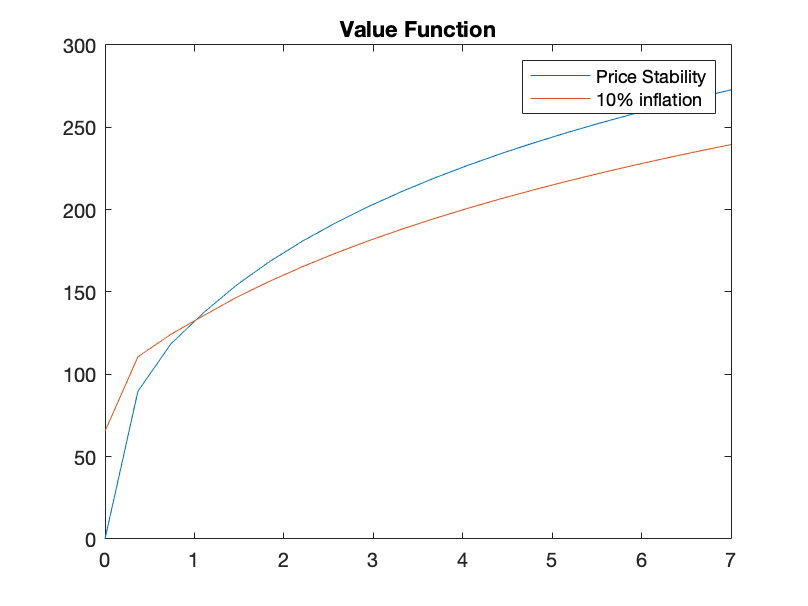

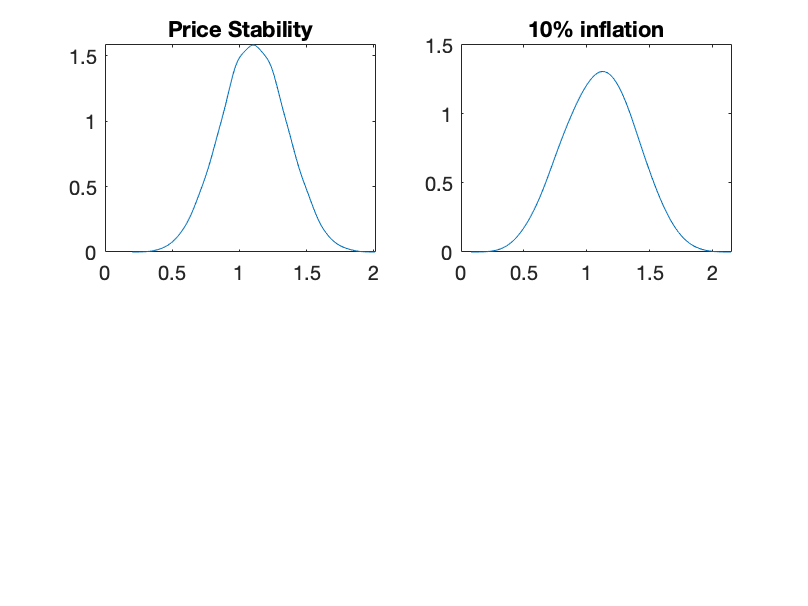

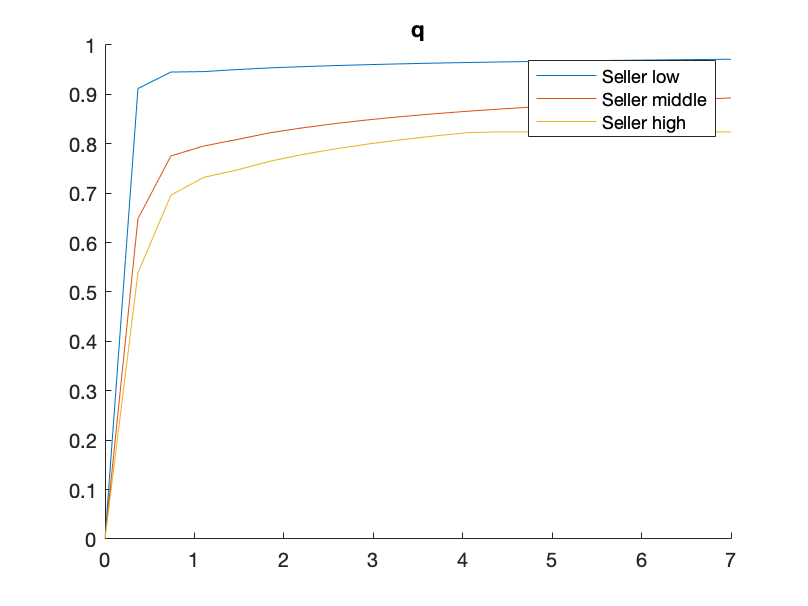

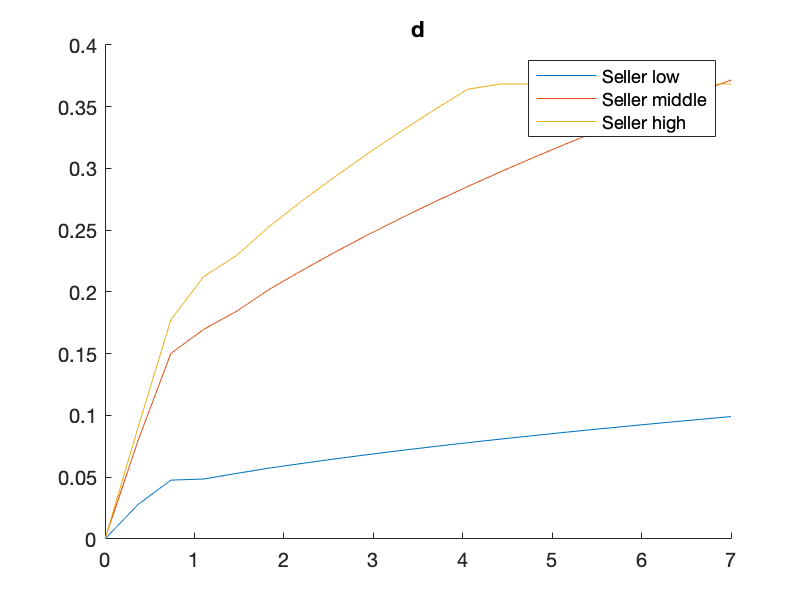

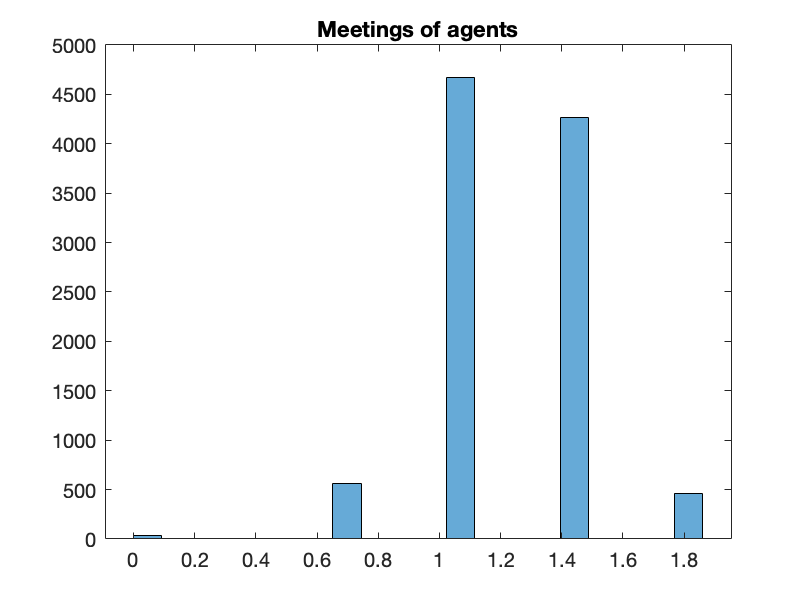

index =      1     2     3     4     5


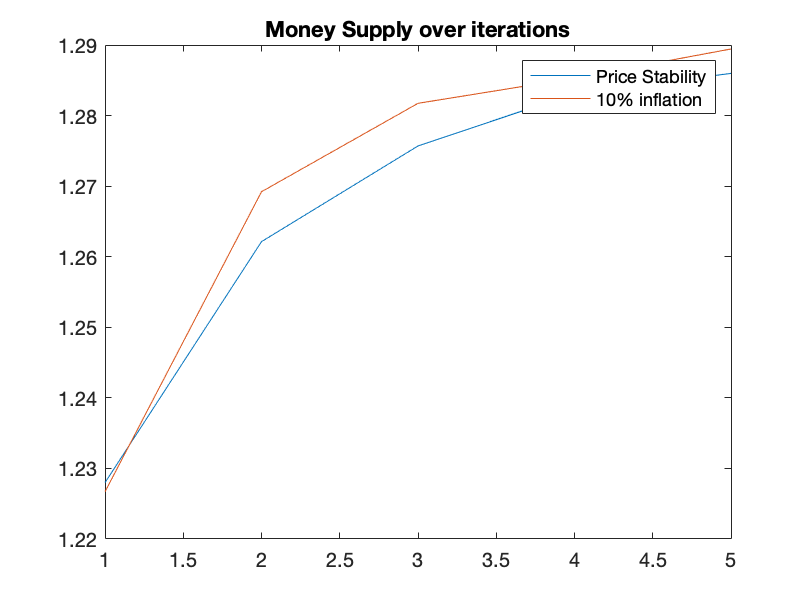

if display_plot_all==1

%Plot V
if display_plot_V==1
figure(1)
plot(m,V_all)
title('Value Function')
legend(mu_labels)

 end


%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
Distribution_all(Distribution_all==0)=0.001;
    figure(2)
    hold on
for l=1:n_calibration
[f(:,l),xi(:,l)] = ksdensity(Distribution_all(:,l),'Support','positive','BoundaryCorrection'...
    ,'reflection','Bandwidth',std(Distribution_all(:,l))*smoothing_parameter); 
    subplot(2,2,l)
plot(xi(:,l),f(:,l))
title(mu_labels(1,l))
 end
end

hold off

%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution_all,grids*2)
 title('Distribution of Money holdings')
 legend(mu_labels)
 end




%Plot q (first iteration)
 if display_plot_q==1
figure(4)
hold on
plot(m,q_all(:,1,1))
plot(m,q_all(:,round(grids/2),1))
plot(m,q_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')

 end




%Plot d (last iteration)
 if display_plot_d==1
figure(5)
hold on
plot(m,d_all(:,1,1))
plot(m,d_all(:,round(grids/2),1))
plot(m,d_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end

%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end



% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
legend(mu_labels)
end

end

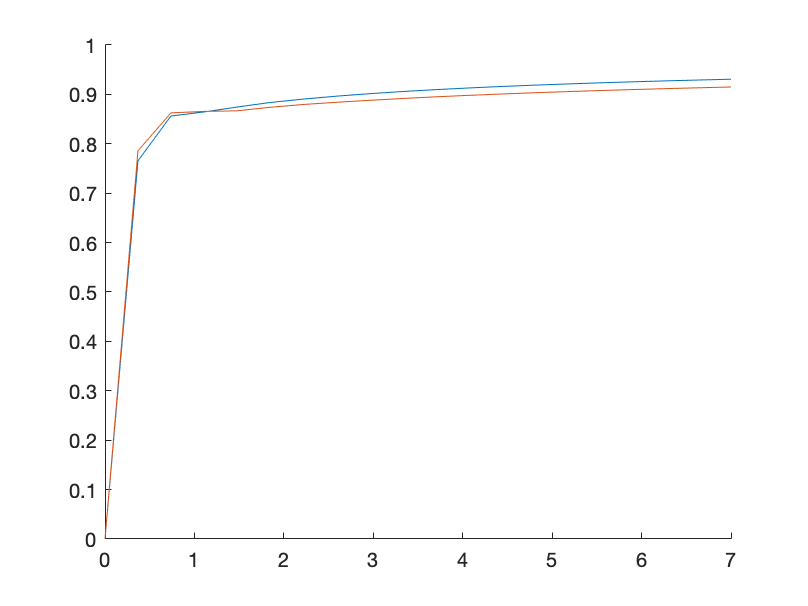

Index in position 3 exceeds array bounds. Index must not exceed 2.


% Plot all q

 if display_plot_q_all==1
figure(10)
hold on
plot(m,q_all(:,3,1))
plot(m,q_all(:,3,2))
plot(m,q_all(:,3,3))
plot(m,q_all(:,3,4))
legend(mu_labels)
hold off
title('Output')
 end


% Plot all d


  if display_plot_d_all==1
figure(11)
hold on
plot(m,d_all(:,3,1))
plot(m,d_all(:,3,2))
plot(m,d_all(:,3,3))
plot(m,d_all(:,3,4))
legend(mu_labels)
hold off
title('Payment')
 end





toc


## Tables

data_table=[average_q;average_price;std_distribution;velocity; average_real_balances]'
figure(20)
 t=uitable(figure,'Data', data_table, 'Position', [100 100 500 200])
set(t, 'columnname', {'q', 'p','std(Dist)','velocity', 'real balances'})
set(t, 'rowname', mu_labels)


## Welfare Cost of Inflation

W=zeros(1,n_calibration);
for j=2:n_calibration
   [W_1,W_2]=cost_of_Inflation(V_all(:,1),V_all(:,j),q_all(:,:,j),lamdba_all(:,j),alpha,x,0.3)
end

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.778214634035802


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.853839034283861


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.856195009854163


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.857584910416727


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.864778733562935


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.870543723891136


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.875088515168887


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.879169484818249


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.882986914762486


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.886454452149015


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.889590126594004


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.892472710463851


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.895141254771290


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.897610576651911


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.899905058633525


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.902046490975490


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.904049863563313


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.905929297827262


Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =    0.907697270980501


W_1 =                    0  -0.413012630357675  -0.111428371592655   0.033435808941214   0.134746032415139   0.210337437126428   0.269208117497918   0.315560056142717   0.353210515263271   0.384534676619293   0.410936262135044   0.433487779617071   0.452995825332438   0.470036970023874   0.485051338001703   0.498382595374714   0.510300311749197   0.521018567676692   0.530711019347415   0.539517618136375


W_2 =                    0  -0.530718149330862  -0.130502784621592   0.039051627907652   0.157122671794285   0.243226884476941   0.309241351249559   0.360603585434801   0.401754748501411   0.435493063589429   0.463572901166912   0.487289333208740   0.507573867549406   0.525098097667243   0.540380595570682   0.553816861671487   0.565713981324121   0.576316184179373   0.585819468053685   0.594380566500530
